# Physical modelling for sound synthesis

*Simon Andersen*

*sand22@student.aau.dk*

## # Analysis

### ## Silvin - Mass Spring system example

With the update equation

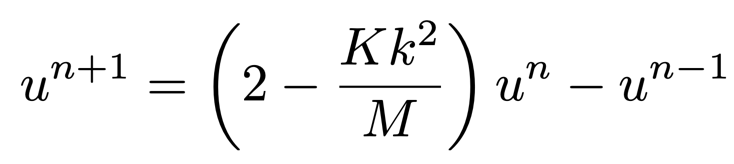

Note that the definition of the update equation can be seen as:

$u^{n+1}$ = uNext

$u^n$     = u

$u^{n-1}$  = uPrev

clear;

% Variables
fs = 44100;                 % fs       : sample rate [Hz]
k = 1 / fs;                 % k        : time step   [s]
duration = fs;              % duration : length of the simulation at 1 second in samples.

f0 = 440;                   % f0       : fundaental frequency [Hz]
omega0 = 2 * pi * f0;       % omega0   : angular (fundamental) frequency [Hz]
M = 1;                      % M        : mass [kg]
K = omega0^2 * M;           % K        : spring constant [N/m]

% Initial conditions
% (u0 = 1, d/dt u0 = 0)
u = 1;
uPrev = 1;

% Sample output vector
out = zeros(duration, 1);

% Simulation loop

for n = 1:duration

    % Update equation
    uNext = (2 - K * k^2 / M) * u - uPrev;

    out(n) = u;

    % Updating system states
    uPrev = u;
    u = uNext;
end

sound(out,fs)


### ## Mass-spring-damper system

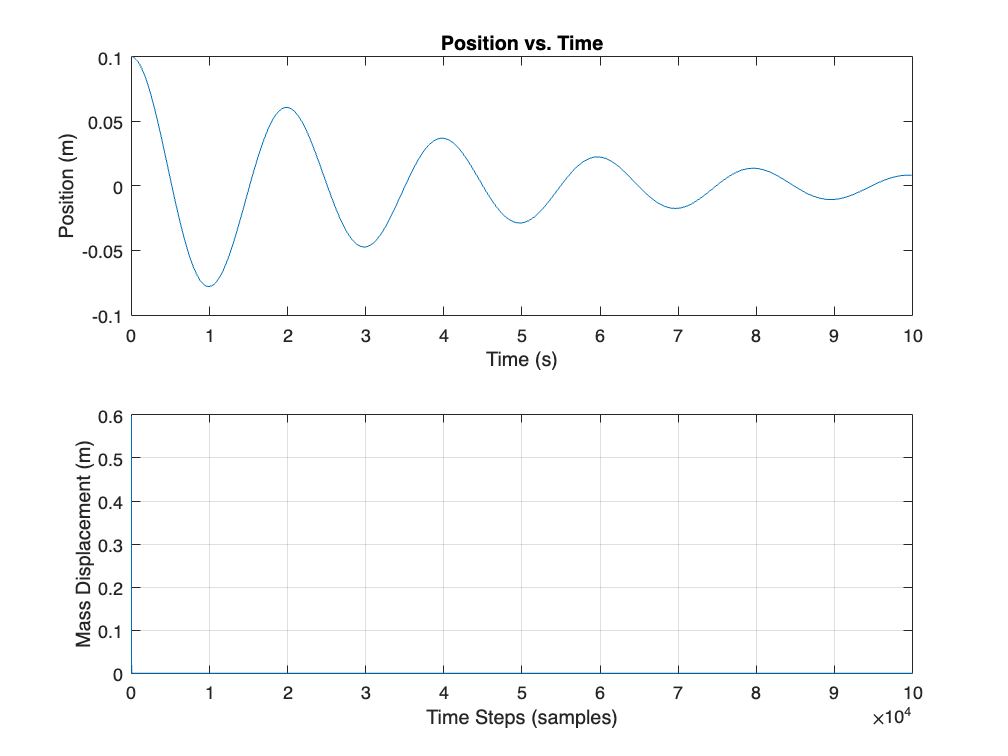

%% Simple Mass-Spring System with Damping:

% Discretized with the "backwards finite difference" equation:
% Equation x[n] = (2*m + b*T / (T*T)*k + m + b*T)*x[n-1] - (m / (T*T)*k + m + b*T)*x[n-2]

clc; clear;

fs = 44200; %samplerate
T = 1/fs;   %sample-period
N = 100000;   %duration

m = 0.1; %mass
k = 500000000;  %spring coefficient
b = 0; % damping coefficient


x = zeros(1,N); %output buffer
xn1 = 1;    % x[n-1] = x[n]
xn2 = 0;

for n=1:N
    
    x(n) = ((2*m + b*T) / ((T*T)*k + m + b*T))*xn1 + (m / ((T*T)*k + m + b*T))*xn2;
    xn2 = xn1;
    xn1 = x(n);
end

plot(x)

grid on
xlabel('Time Steps (samples)'); 
ylabel('Mass Displacement (m)');

soundsc(x,fs);

### ## Silvin - 1D wave equation example

clear;

fs = 44100;                 % fs    : sample rate
k = 1 / fs;                 % k     : time step
d = fs;                     % d     : duration of simulation

c = 300;                    % c     : wave speed
L = 1;                      % L     : length
h = c * k;                  % h     : grid spacing (from CFL condition)
N = floor(L/h);             % N     : Number of intervals between grid points
h = L / N;                  % h     : Recalculating grid spacing based on interger N

lSq = c^2 * k^2 / h^2;      % lSq   : Courant number squared

% Setting up boundary conditions
bcLeft = "D";
bcRight = "D";

% State vectors
uNext = zeros(N+1, 1);      % uNext : u^n+1
u = zeros(N+1, 1);          % u     : u^n

% Initial conditions (raised cosine)
loc = round(0.8 * N);       % loc   : Center location
hW = round(N/10);           % hW    : Half-width of raised cosine
w = 2 * hW;                 % w     : Full width
rcX = 0:w;                  % rcX   : x-locations for raised cosine

                            % rc    : Raised cosine
rc = 0.5 - 0.5 * cos(2* pi * rcX / w);

% Init current state
u(loc-hW : loc+hW) = rc;    


% Set initial velocity to zero
uPrev = u;

% Range of calculation
range = 2:N;

% Output location
outLoc = round(0.3 * N);

% Simulation loop
for n = 1:d
    % Update equation
    uNext(range) = (2 - 2 * lSq) * u(range) ...
        + lSq * u(range + 1) ...
        + u(range - 1) - uPrev(range);

    % boundary updates
    if bcLeft == "N"
        uNext(1) = (2 - 2 * lSq) ...
            * u(1) - uPrev(1) ...
            + 2 * lSq * u(2);
    end

    if bcRight == "N"
        uNext(N+1) = (2 - 2 * lSq) ...
            * u(N+1) - uPrev(N+1) ...
            + 2 * lSq * u(N);
    end

    out(n)=u(outLoc);

    uPrev = u;
    u = uNext;
end

sound(out, fs);

### ## Silvin - 2D wave equation example

clear;

fs = 44100;
k = 1 / fs;
d = fs;

rho = 7850;
H = 0.0005;
T = 1000000;
c = sqrt(T / (rho * H));

Lx = 1;
Ly = 2;

h = sqrt(2) * c * k;
Nx = floor(Lx/h);
Ny = floor(Ly/h);
h = min(Lx/Nx, Ly/Ny);

lambdaSq = c^2 * k^2 / h^2;
h = max(Lx/Nx, Ly/Ny);

Nxu = Nx - 1;
Nyu = Ny - 1;
Dxx = toeplitz([-2, 1, zeros(1, Nxu - 2)]);
Dyy = toeplitz([-2, 1, zeros(1, Nyu - 2)]);

D = kron(speye(Nxu), Dyy) + kron(Dxx, speye(Nyu));
D = D / h^2;

Nu = Nxu * Nyu;

uNext = zeros(Nu, 1);
u = zeros(Nu, 1);

halfWidth = floor(min(Nx, Ny) / 5);
width = 2 * halfWidth + 1;
xLoc = floor(0.3 * Nx);
yLoc = floor(0.6 * Ny);
xRange = xLoc-halfWidth : xLoc+halfWidth;
yRange = yLoc-halfWidth : yLoc+halfWidth;

rcMat = zeros(Nyu, Nxu);
rcMat(yRange, xRange) = hann(width) * hann(width)';

u = reshape(rcMat, Nu, 1);

uPrev = u;

xOut = 0.45;
yOut = 0.25;
outLoc = round((xOut + yOut * Nyu) * Nxu);
out = zeros(d, 1);

for n = 1:d
    uNext = (2 * eye(Nu) + c^2 * k^2 * D) * u - uPrev;

    uPrev = u;
    u = uNext;
end

sound(out, fs);

### ## Silvin - 2D wave equation

clear;

%% Initialise variables
fs = 44100; % Sample rate [Hz]
k = 1 / fs; % Time step [s]
lengthSound = fs; % Length of the simulation (1 second) [samples]


rho = 7850; % Material density [kg/m^3]
H =  0.0005; % Thickness [m]
T = 1000000; % Tension per unit length [N/m]
c = sqrt(T / (rho * H)); % Wave speed [m/s]


Lx = 1; % Length in x direction [m]
Ly = 2; % Length in y direction [m] 


h=sqrt(2) * c * k; % Grid spacing [m]
Nx = floor(Lx/h); % Number of intervals in x direction
Ny = floor(Ly/h); % Number of intervals in y direction
h = min(Lx/Nx, Ly/Ny); % Recalculation of grid spacing

lambdaSq = c^2 * k^2 / h^2; % Courant number squared
h = max(Lx/Nx, Ly/Ny);% Recalculation of grid spacing


%% Create scheme matrices with Dirichlet boundary conditions
Nxu = Nx - 1;
Nyu = Ny - 1;
Dxx = toeplitz([-2, 1, zeros(1, Nxu-2)]);
Dyy = toeplitz([-2, 1, zeros(1, Nyu-2)]);

% Kronecker sum
D = kron(speye(Nxu), Dyy) + kron(Dxx, speye(Nyu));
D = D / h^2;

% Total number of grid points
Nu = Nxu * Nyu;


%% Initialise state vectors (one more grid point than the number of intervals)
uNext = zeros(Nu, 1);
u = zeros(Nu, 1);

%% Initial conditions (2D raised cosine)
halfWidth = floor(min(Nx, Ny) / 5);
width = 2 * halfWidth + 1;
xLoc = floor(0.3 * Nx);
yLoc = floor(0.6 * Ny);
xRange = xLoc-halfWidth : xLoc+halfWidth;
yRange = yLoc-halfWidth : yLoc+halfWidth;


rcMat = zeros(Nyu, Nxu);
rcMat(yRange, xRange) = hann(width) * hann(width)';


% initialise current state
u = reshape(rcMat, Nu, 1);


% Set initial velocity to zero
uPrev = u;

% Output location
xOut = 0.45;
yOut = 0.25;
outLoc = round((xOut + yOut * Nyu) * Nxu);
out = zeros(lengthSound, 1);


%% Simulation loop
for n = 1:lengthSound
    
    %% Update equation Eq. (6.21)
    uNext = (2 * eye(Nu) + c^2 * k^2 * D) * u - uPrev;
    
    
    % Update system states
    uPrev = u;
    u = uNext;
end




### ## Mass-spring-damper model

*Simulating the sound of a marimba*

clear;

% Parameters
num_segments = 10;          % Number of segments for each bar
num_bars = 5;               % Number of bars in the marimba
duration = 2.0;             % Duration of the simulation in seconds
fs = 44100;                 % Sample rate

% Mass-Spring-Damper Properties
mass_per_segment = 0.01;    % Mass of each segment (kg)
stiffness = 1000;           % Stiffness of the springs (N/m)
damping_ratio = 0.1;        % Damping ratio (0.0 - 1.0)

% Excitation properties
mallet_force = 0.1;         % Force applied by the mallet (N)
mallet_segment = 3;         % Segment where the mallet strikes (1 to num_segments)

% Time vector
dt = 1 / fs;
t = 0:dt:duration;
num_samples = length(t);

% Position & velocities of masses
positions = zeros(num_bars, num_segments);
velocities = zeros(num_bars, num_segments);

% Output vector
output = zeros(num_samples, 1);

% Simulation loop
for n = 1:num_samples

    if n == 1
        excitation_force = mallet_force / mass_per_segment;
    else
        excitation_force = 0;
    end

    % Update positions and velocities using Euler integration
    for bar = 1:num_bars
        for segment = 1:num_segments
            if segment == 1
                spring_force = stiffness * (positions(bar, segment+1) - positions(bar, segment));
            elseif segment == num_segments
                spring_force = stiffness * (positions(bar, segment-1) - positions(bar, segment));
            else
                spring_force = stiffness * ((positions(bar, segment-1) - positions(bar, segment)) + ...
                                                (positions(bar, segment+1) - positions(bar, segment)));
            end

            damper_force = -damping_ratio * velocities(bar, segment);
            total_force = excitation_force + spring_force + damper_force;

            acceleration = total_force / mass_per_segment;

            velocities(bar, segment) = velocities(bar, segment) + acceleration * dt;
            positions(bar, segment) = positions(bar, segment) + velocities(bar, segment) * dt;
        end
    end

    output = output / max(abs(output));

    sound(output, fs);

    plot(t, output);

    xlabel('Time (s)');
    ylabel('Amplitude')
    title('Simulated Marimba Sound')
    grid on;
end

### # Simulating a Marimba using the ideal bar concept

clear;
% Parameters
num_bars = 5;              % Number of bars in the marimba
duration = 2.0;            % Duration of the simulation in seconds
sample_rate = 44100;       % Audio sample rate (Hz)

% Ideal Bar Properties
bar_length = 1.0;          % Length of the bar (m)
bar_width = 0.02;          % Width of the bar (m)
bar_thickness = 0.01;      % Thickness of the bar (m)
material_density = 7850;   % Density of the bar material (kg/m^3)
material_stiffness = 2e11; % Stiffness of the bar material (N/m^2)

% Excitation Properties
mallet_force = 0.1;        % Force applied by the mallet (N)
mallet_position = 0.3;     % Position where the mallet strikes (0.0 - 1.0)

% Create time vector
dt = 1/sample_rate;
t = 0:dt:duration;
num_samples = length(t);

% Initialize positions of the bar
positions = zeros(num_bars, 1);

% Initialize the sound buffer
sound_buffer = zeros(num_samples, 1);

% Simulation loop
for n = 1:num_samples

% Compute excitation force (impulse at mallet_position)

    if n == 1
        excitation_force = mallet_force / (bar_width * bar_thickness);
    else
        excitation_force = 0;
    end

    % Update positions using Euler integration
    for bar = 1:num_bars
        acceleration = excitation_force / (material_density * bar_width * bar_thickness);
        positions(bar) = positions(bar) + acceleration * dt^2;

        % Reflect energy at the endpoints
        if positions(bar) < 0
            positions(bar) = abs(positions(bar));
        elseif positions(bar) > bar_length
            positions(bar) = 2 * bar_length - positions(bar);
        end
    end

    % Synthesize sound from the positions of the bars
    sound_buffer(n) = sum(positions);

end

% Normalize the sound buffer
sound_buffer = sound_buffer / max(abs(sound_buffer));

% Play the sound
sound(sound_buffer, sample_rate);

% Plot the sound waveform
plot(t, sound_buffer);
xlabel('Time (s)');
ylabel('Amplitude');
title('Simulated Marimba Sound (Ideal Bar Model)');
grid on;

### # Another marimba concept

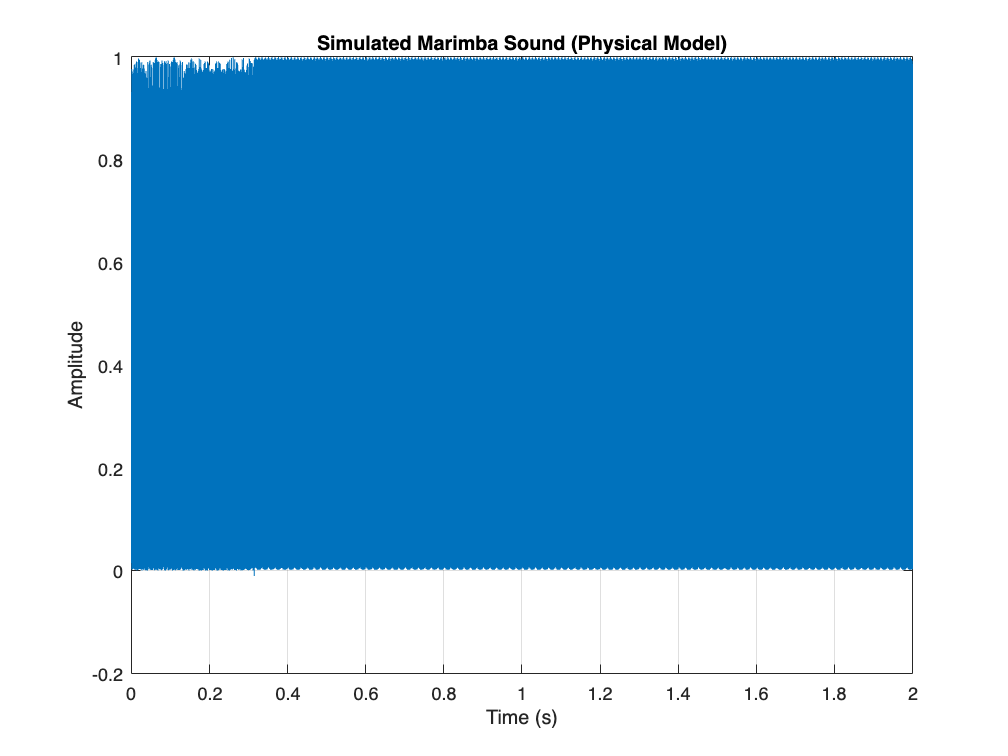

clear;

% Parameters
num_bars = 5;              % Number of bars in the marimba
duration = 2.0;            % Duration of the simulation in seconds
sample_rate = 44100;       % Audio sample rate (Hz)

% Bar Properties
bar_length = 0.5;          % Length of the bar (m)
bar_thickness = 0.1;      % Thickness of the bar (m)
material_density = 7850;   % Density of the bar material (kg/m^3)
material_stiffness = 2e11; % Stiffness of the bar material (N/m^2)

% Excitation Properties
mallet_force = 0.00001;        % Force applied by the mallet (N)
mallet_position = 0.3;     % Position where the mallet strikes (0.0 - 1.0)

% Create time vector
dt = 1/sample_rate;
t = 0:dt:duration;
num_samples = length(t);

% Initialize positions, velocities, and accelerations of the bars
positions = zeros(num_bars, 1);
velocities = zeros(num_bars, 1);
accelerations = zeros(num_bars, 1);

% Initialize the sound buffer
sound_buffer = zeros(num_samples, 1);

% Simulation loop
for n = 1:num_samples

    % Compute excitation force (impulse at mallet_position)
    if n == 1
        excitation_force = mallet_force / (bar_thickness);
    else
        excitation_force = 0;
    end

    % Update positions, velocities, and accelerations using explicit finite difference
    for bar = 1:num_bars
        spring_force = -material_stiffness * (positions(bar) - bar_length); % Hooke's law
        damping_force = -0.01 * velocities(bar); % Damping (adjust the damping coefficient)
        total_force = excitation_force + spring_force + damping_force;
        
        accelerations(bar) = total_force / (material_density * bar_thickness);
        velocities(bar) = velocities(bar) + accelerations(bar) * dt;
        positions(bar) = positions(bar) + velocities(bar) * dt;
        
        % Reflect energy at the endpoints
        if positions(bar) < 0
            positions(bar) = abs(positions(bar));
            velocities(bar) = -velocities(bar);
        elseif positions(bar) > bar_length
            positions(bar) = 2 * bar_length - positions(bar);
            velocities(bar) = -velocities(bar);
        end
    end

    % Synthesize sound from the positions of the bars
    sound_buffer(n) = sum(positions);

end

% Normalize the sound buffer
sound_buffer = sound_buffer / max(abs(sound_buffer));

% Play the sound
% sound(sound_buffer, sample_rate);

% Plot the sound waveform
plot(t, sound_buffer);
xlabel('Time (s)');
ylabel('Amplitude');
title('Simulated Marimba Sound (Physical Model)');
grid on;

### ## Bilbao ideal bar

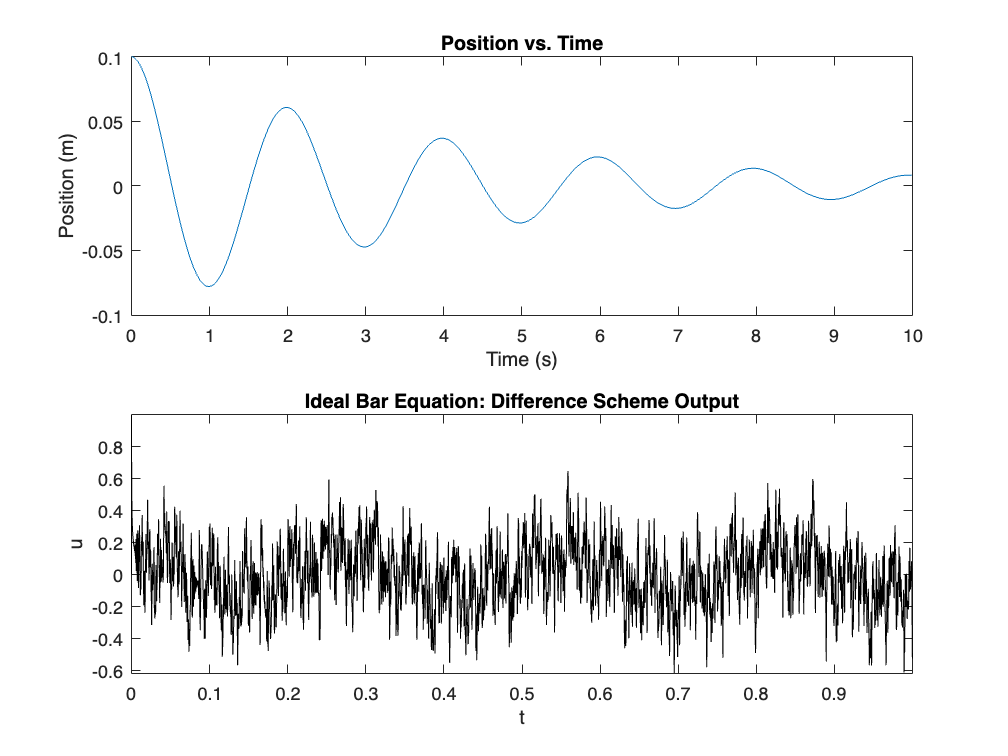

% matlab script idealbarfd.m
% finite difference scheme for the ideal bar equation 
% *fixed boundary conditions
% *raised cosine initial conditions

%%%%%% begin global parameters

SR = 44100;                                     % sample rate (Hz)
K = 1;                                          % stiffness parameter
TF = 1;                                         % duration of simulation (s)
ctr = 0.5;                                      % center location of excitation (0-1)
wid = 0.1;                                      % width of excitation 
u0 = 1;                                         % maximum initial displacement
v0 = 0;                                         % maximum initial velocity
mu = 0.5;                                       % scheme free parameter
rp = 0.5;                                      % position of readout (0-1)

%%%%%% end global parameters

%%%%%% begin derived parameters

k = 1/SR;                                       % time step
NF = floor(SR*TF);                              % duration of simulation (samples)
h = sqrt(K*k/mu);                               % grid spacing
N = floor(1/h);                                 % number of subdivisions of spatial domain
h = 1/N;                                        % reset h 
mu = K*k/h^2;                                   % reset Courant number
s0 = 2*(1-3*mu^2); s1 = 4*mu^2; s2 = -mu^2;     % scheme parameters  
rp_int = 1+floor(N*rp);                         % rounded grid index for readout
rp_frac = 1+rp/h-rp_int;                        % fractional part of readout location

%%%%%% initialize grid functions and output

u = zeros(N+1,1); u1 = zeros(N+1,1); u2 = zeros(N+1,1); 
out = zeros(NF,1); 

%%%%%% create raised cosine

rc = zeros(N+1,1);
for qq=1:N+1
    pos = (qq-1)*h; dist = ctr-pos; 
    if(abs(dist)<=wid/2)
        rc(qq) = 0.5*(1+cos(2*pi*dist/wid));
    end
end

%%%%%% set initial conditions

u2 = u0*rc; u1 = (u0+k*v0)*rc; 

%%%%%% start main loop

for n=3:NF
    u(3:N-1) = -u2(3:N-1)+s0*u1(3:N-1)+s1*(u1(2:N-2)+u1(4:N))...
        +s2*(u1(1:N-3)+u1(5:N+1));                          % scheme calculation
    out(n) = (1-rp_frac)*u(rp_int)+rp_frac*u(rp_int+1);     % readout
    u2 = u1; u1 = u;                                        % update of grid variables
end

%%%%% end main loop

% plot output waveform

plot([0:NF-1]*k, out, 'k'); 
xlabel('t'); ylabel('u'); title('Ideal Bar Equation: Difference Scheme Output');
axis tight


% play sound

soundsc(out,SR);   

### ## Another marimba example from ChatGPT

clear;
% Parameters
bar_length = 1.0;           % Length of the bar (m)
bar_thickness = 0.01;       % Thickness of the bar (m)
material_density = 7850;    % Density of the bar material (kg/m^3)
material_stiffness = 2e11;  % Stiffness of the bar material (N/m^2)
damping_coefficient = 0.01; % Damping coefficient

% Excitation Properties
mallet_force = 0.1;         % Force applied by the mallet (N)
excitation_position = 0.3;  % Position where the mallet strikes (0.0 - 1.0)

% Simulation Parameters
duration = 1.0;             % Duration of the simulation (s)
sample_rate = 44100;        % Audio sample rate (Hz)

% Initialize variables
dt = 1/sample_rate;
num_samples = duration * sample_rate;
positions = zeros(num_samples, 1);
velocities = zeros(num_samples, 1);
accelerations = zeros(num_samples, 1);

% Excitation force
excitation_index = round(excitation_position * bar_length * sample_rate);
excitation_force = mallet_force / (bar_thickness);

% Simulation loop
for n = 1:num_samples
    if n == 1
        accelerations(n) = excitation_force / (material_density * bar_thickness);
    else
        spring_force = -material_stiffness * positions(n-1);
        damping_force = -damping_coefficient * velocities(n-1);
        accelerations(n) = (excitation_force + spring_force + damping_force) / (material_density * bar_thickness);
    end

    if n < num_samples
        velocities(n+1) = velocities(n) + accelerations(n) * dt;
        positions(n+1) = positions(n) + velocities(n+1) * dt;
    end
end

% Normalize sound
sound_buffer = positions / max(abs(positions));

velocities

velocities = 1.0e+301 *

         0
    0.0000
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000


positions

positions = 1.0e+297 *

         0
    0.0000
    0.0000
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0000


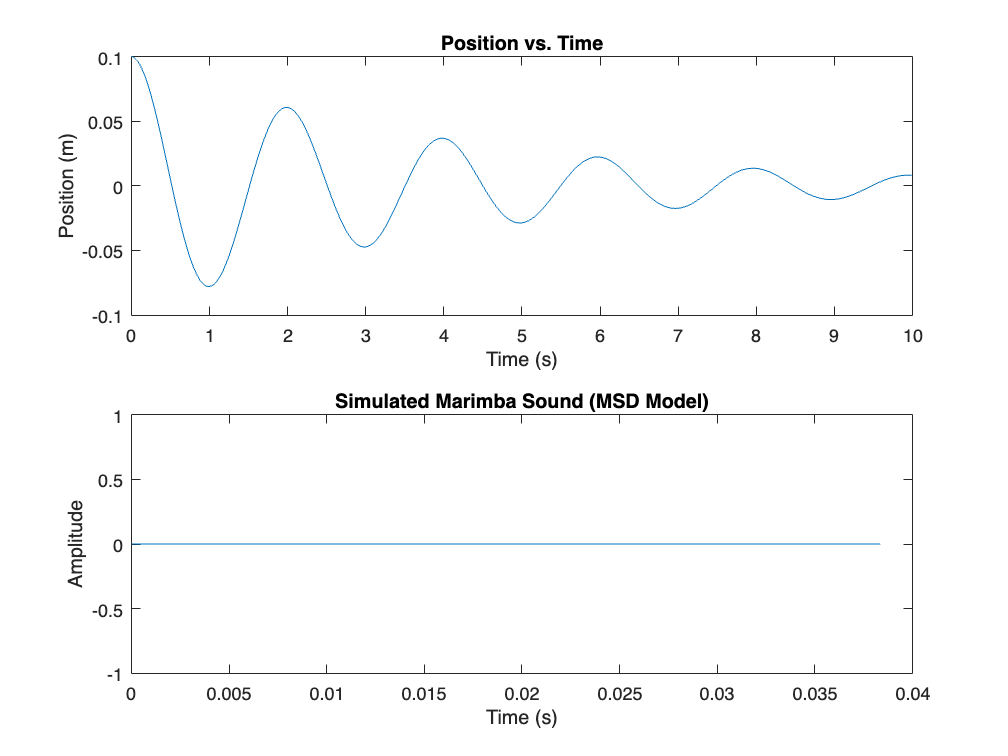


% Play sound
% sound(sound_buffer, sample_rate);

% Plot sound waveform
t = (0:num_samples-1) / sample_rate;
plot(t, sound_buffer);
xlabel('Time (s)');
ylabel('Amplitude');
title('Simulated Marimba Sound (MSD Model)');

### ## Ideal bar ChatGPT

clear;

% Parameters
bar_length = 1.0;           % Length of the bar (m)
bar_thickness = 0.01;       % Thickness of the bar (m)
material_density = 7850;    % Density of the bar material (kg/m^3)
material_stiffness = 2e11;  % Stiffness of the bar material (N/m^2)
damping_coefficient = 0.01; % Damping coefficient

% Excitation Properties
mallet_force = 0.1;         % Force applied by the mallet (N)
excitation_position = 0.3;  % Position where the mallet strikes (0.0 - 1.0)

% Simulation Parameters
duration = 2.0;             % Duration of the simulation (s)
sample_rate = 44100;        % Audio sample rate (Hz)

% Initialize variables
dt = 1/sample_rate;
num_samples = duration * sample_rate;
positions = zeros(num_samples, 1);

% Excitation force
excitation_index = round(excitation_position * bar_length * sample_rate);
excitation_force = mallet_force / (bar_thickness);

% Calculate properties
bar_area = bar_thickness * bar_thickness;  % Cross-sectional area of the bar
mass_per_unit_length = material_density * bar_area;
wave_speed = sqrt(material_stiffness / material_density);

% Simulation loop
for n = 1:num_samples
    if n == excitation_index
        positions(n) = excitation_force / (2 * material_stiffness);
    else
        if n > 1
            acceleration = (positions(n-1) - 2 * positions(n) + positions(n+1)) / (bar_length^2) ...
                         * material_stiffness / mass_per_unit_length;
            velocity = positions(n) - positions(n-1);
            damping_force = -damping_coefficient * velocity;
            positions(n+1) = positions(n) + velocity + acceleration * dt + damping_force * dt^2 / (2 * mass_per_unit_length);
        elseif n < 88200
                break
        end
    end
end

% Normalize sound
sound_buffer = positions / max(abs(positions));

positions

positions =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


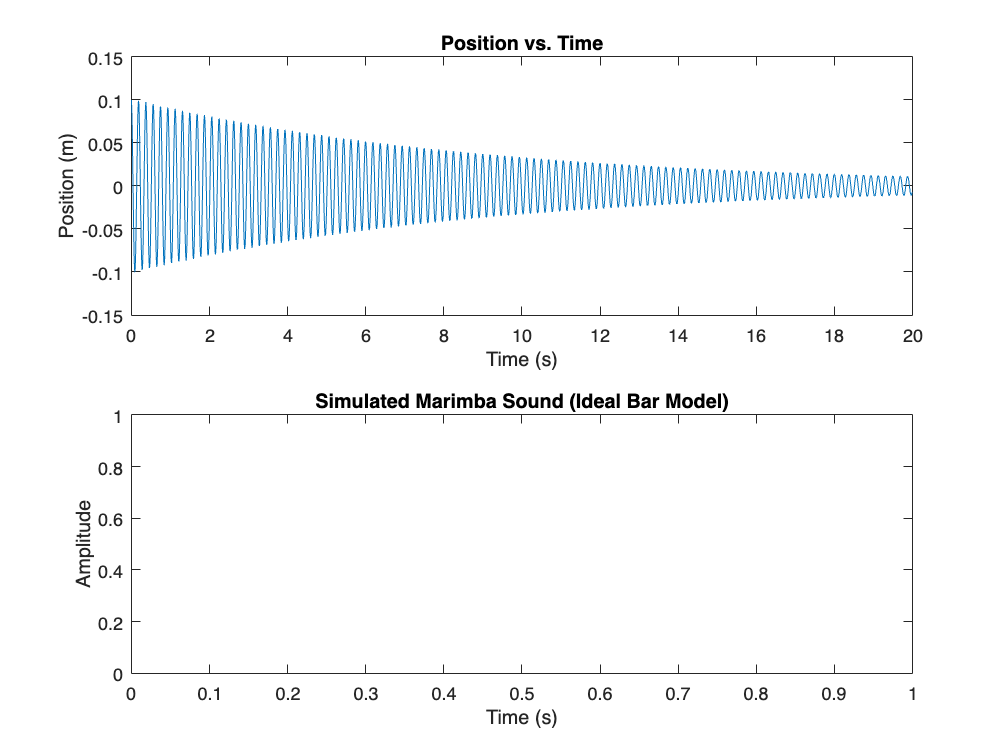


% Play sound
% sound(sound_buffer, sample_rate);

% Plot sound waveform
t = (0:num_samples-1) / sample_rate;
plot(t, sound_buffer);
xlabel('Time (s)');
ylabel('Amplitude');
title('Simulated Marimba Sound (Ideal Bar Model)');

### ChatGPT Marimba explanation

In the context of musical instruments, the exciter-resonator relationship refers to how an instrument is set into vibration and how those vibrations interact with the resonating elements of the instrument to produce sound. For a marimba, the exciter is typically the mallet that strikes the bars, and the resonator is the bar itself. Let's break down this relationship:

#### 1. Exciter:

The exciter is the external force or action that initiates the vibration in the instrument. In the case of a marimba, the exciter is the mallet that strikes the bars. When the mallet hits a bar, it imparts energy to the bar in the form of kinetic energy. The mallet's impact creates a force that leads to the initial displacement of the bar from its equilibrium position.

#### 2. Resonator:

The resonator is the element of the instrument that vibrates in response to the excitation and produces sound. In the marimba, the resonator is the bar itself. After being struck by the mallet, the bar vibrates at its natural frequencies, which are determined by its length, thickness, material properties, and physical characteristics.

#### Excitation-Resonance Interaction:

When the mallet strikes a marimba bar, it generates vibrations that propagate through the bar's structure. These vibrations interact with the resonating modes of the bar, which are essentially its natural frequencies of vibration. Each bar has a set of resonant modes that correspond to specific pitches. As the bar vibrates, it radiates sound waves into the surrounding air, creating the audible tones that we hear as the marimba's sound.

The interaction between the exciter (mallet) and the resonator (bar) is what gives the marimba its characteristic sound. The unique combination of the mallet's impact and the bar's resonant properties determines the pitch, timbre, and overall quality of the sound produced by the instrument. Different parts of the bar may vibrate differently based on where they are struck, leading to variations in pitch and tonal color.

In more complex physical modeling of the marimba, the exciter-resonator relationship is simulated using techniques like the Mass-Spring-Damper (MSD) model. The excitation force (impact of the mallet) leads to vibrations in the bars (resonators), and these vibrations propagate through the bar's structure, resulting in the generation of sound waves that match the resonant frequencies of the bars.

Overall, the exciter-resonator relationship is a fundamental concept in understanding how musical instruments like the marimba produce sound through the interaction of external forces and resonating elements.

### ## Mass-spring damper system


clear;
% Parameters
mass = 0.9;                % Mass (kg)
spring_constant = 1000;    % Spring constant (N/m)
damping_coefficient = 0.2; % Damping coefficient (N*s/m)

% Initial conditions
initial_position = 0.1;   % Initial position (m)
initial_velocity = 0;     % Initial velocity (m/s)

% Simulation parameters
duration = 20;            % Duration of simulation (s)
time_step = 0.01;         % Time step (s)
num_steps = duration / time_step;

% Initialize arrays to store position and velocity
positions = zeros(1, num_steps);
velocities = zeros(1, num_steps);

% Set initial conditions
positions(1) = initial_position;
velocities(1) = initial_velocity;

% Simulation loop
for step = 2:num_steps
    % Calculate forces
    spring_force = -spring_constant * positions(step-1);
    damping_force = -damping_coefficient * velocities(step-1);
    
    % Calculate acceleration
    acceleration = (spring_force + damping_force) / mass;
    
    % Update velocity and position using numerical integration
    velocities(step) = velocities(step-1) + acceleration * time_step;
    positions(step) = positions(step-1) + velocities(step) * time_step;
end

% Plot the results
time = 0:time_step:duration;
time(end) = [];

positions

positions =     0.1000    0.0889    0.0679    0.0395    0.0067   -0.0268   -0.0572   -0.0812   -0.0961   -0.1003   -0.0933   -0.0760   -0.0503   -0.0191    0.0142    0.0459    0.0723    0.0907    0.0990    0.0962    0.0828    0.0602    0.0309   -0.0017   -0.0341   -0.0625   -0.0840   -0.0961   -0.0975   -0.0881   -0.0689   -0.0420   -0.0106    0.0219    0.0520    0.0762    0.0918    0.0973    0.0919    0.0763    0.0523    0.0225   -0.0097   -0.0408   -0.0672   -0.0862   -0.0955   -0.0942   -0.0824   -0.0615


velocities

velocities =          0   -1.1111   -2.0963   -2.8464   -3.2785   -3.3454   -3.0405   -2.3984   -1.4912   -0.4203    0.6948    1.7303    2.5712    3.1246    3.3296    3.1641    2.6475    1.8378    0.8257   -0.2758   -1.3443   -2.2610   -2.9245   -3.2615   -3.2354   -2.8499   -2.1486   -1.2101   -0.1392    0.9447    1.9213    2.6822    3.1434    3.2544    3.0034    2.4193    1.5677    0.5438   -0.5382   -1.5581   -2.4025   -2.9782   -3.2216   -3.1066   -2.6466   -1.8936   -0.9319    0.1313    1.1775    2.0905


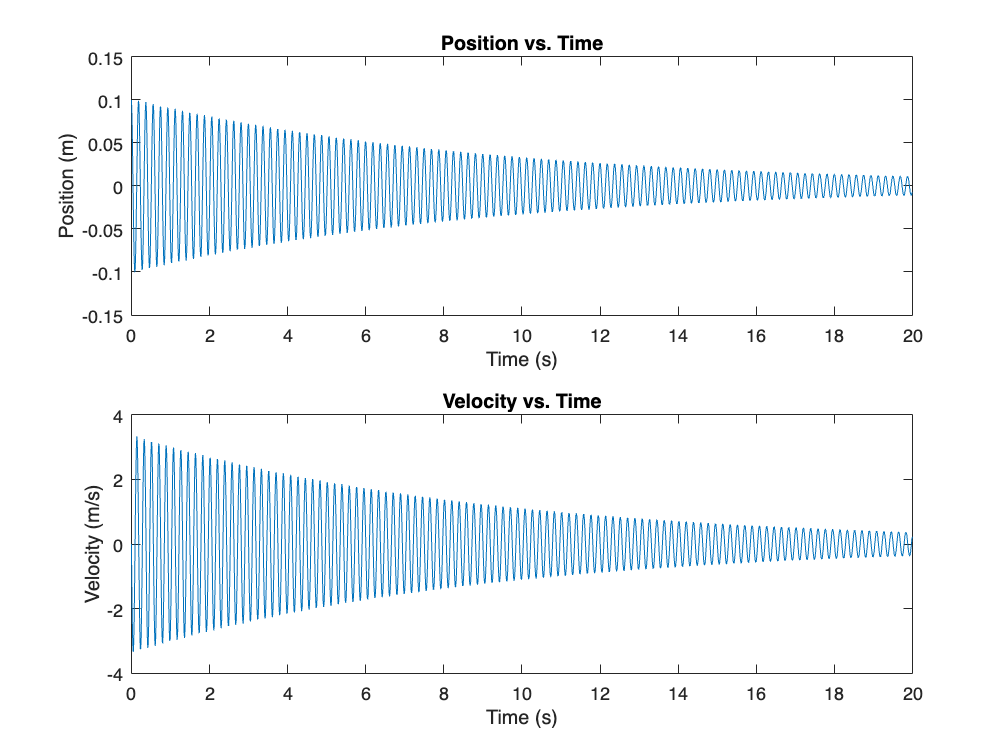


sound(velocities)

figure;
subplot(2,1,1);
plot(time, positions);
xlabel('Time (s)');
ylabel('Position (m)');
title('Position vs. Time');
subplot(2,1,2);
plot(time, velocities);
xlabel('Time (s)');
ylabel('Velocity (m/s)');
title('Velocity vs. Time');

### ## Previous example being rewritten

clc; clear;
% Parameters
mass = 0.2;                % Mass (kg)
spring_constant = 100000;    % Spring constant (N/m)
damping_coefficient = 0.5; % Damping coefficient (N*s/m)

% Initial conditions
initial_position = 0.1;   % Initial position (m)
initial_velocity = 0;     % Initial velocity (m/s)

% Simulation parameters
fs = 44100;
duration = fs;            % Duration of simulation (s)
time_step = 1 / fs;         % Time step (s)


% Initialize arrays to store position and velocity
positions = zeros(1, duration);
velocities = zeros(1, duration);

% Set initial conditions
positions(1) = initial_position;
velocities(1) = initial_velocity;

% Simulation loop
for step = 2:duration
    % Calculate forces
    spring_force = -spring_constant * positions(step-1);
    damping_force = -damping_coefficient * velocities(step-1);
    
    % Calculate acceleration
    acceleration = (spring_force + damping_force) / mass;
    
    % Update velocity and position using numerical integration
    velocities(step) = velocities(step-1) + acceleration * time_step;
    positions(step) = positions(step-1) + velocities(step) * time_step;
end

% Plot the results
time = 1:1:duration;

positions

positions =     0.1000    0.1000    0.0999    0.0998    0.0997    0.0996    0.0995    0.0993    0.0991    0.0988    0.0986    0.0983    0.0980    0.0977    0.0973    0.0969    0.0965    0.0961    0.0956    0.0952    0.0947    0.0941    0.0936    0.0930    0.0924    0.0918    0.0911    0.0904    0.0897    0.0890    0.0883    0.0875    0.0867    0.0859    0.0851    0.0842    0.0834    0.0825    0.0816    0.0806    0.0797    0.0787    0.0777    0.0767    0.0756    0.0746    0.0735    0.0724    0.0713    0.0702


velocities

velocities =          0   -1.1338   -2.2672   -3.4000   -4.5318   -5.6625   -6.7916   -7.9188   -9.0440  -10.1668  -11.2870  -12.4041  -13.5180  -14.6284  -15.7349  -16.8373  -17.9354  -19.0288  -20.1172  -21.2003  -22.2780  -23.3499  -24.4157  -25.4752  -26.5281  -27.5740  -28.6129  -29.6443  -30.6680  -31.6839  -32.6914  -33.6906  -34.6810  -35.6625  -36.6347  -37.5974  -38.5504  -39.4935  -40.4264  -41.3488  -42.2605  -43.1613  -44.0510  -44.9293  -45.7959  -46.6508  -47.4936  -48.3242  -49.1423  -49.9477


time

time =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


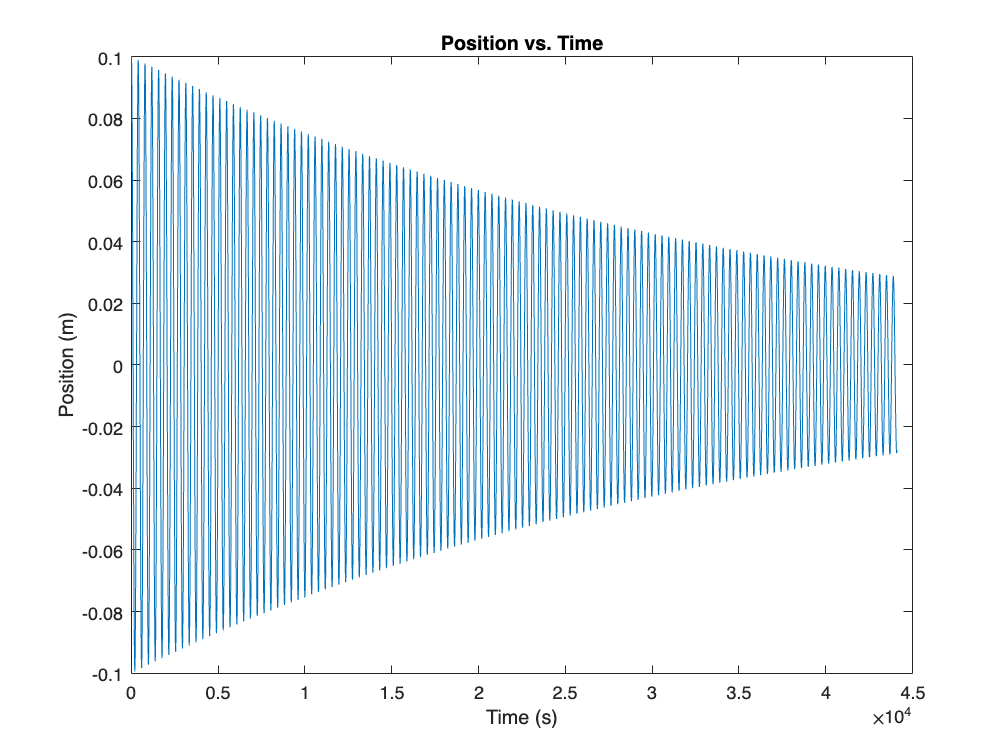


sound(positions, fs)


plot(time, positions);
xlabel('Time (s)');
ylabel('Position (m)');
title('Position vs. Time');

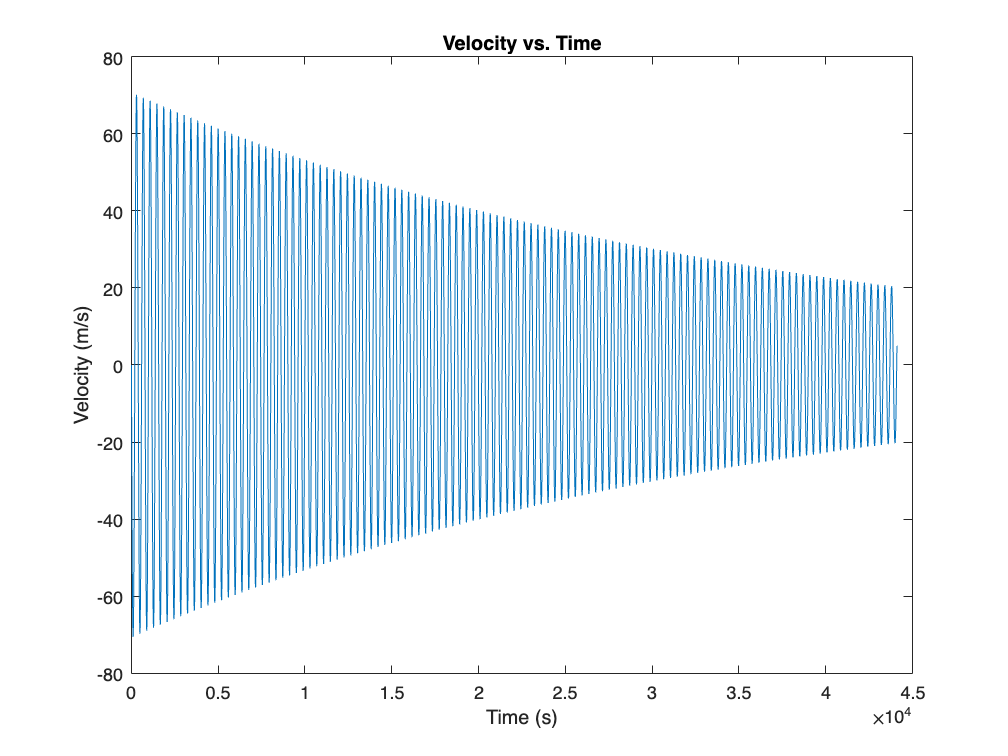


plot(time, velocities);
xlabel('Time (s)');
ylabel('Velocity (m/s)');
title('Velocity vs. Time');

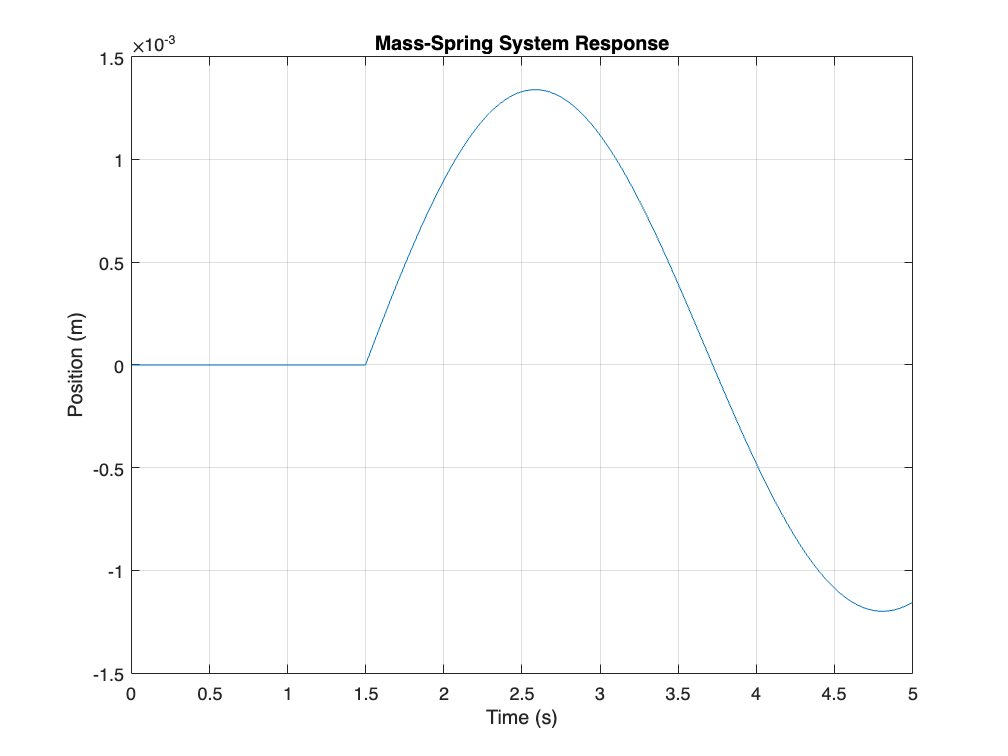

clc; clear;

% Parameters
mass = 5;               % Mass (kg)
spring_constant = 10;   % Spring constant (N/m)
damping_coefficient = 0.5; % Damping coefficient (N*s/m)

% Initial conditions
initial_position = 0;   % Initial position (m)
initial_velocity = 0;   % Initial velocity (m/s)

% Simulation parameters
duration = 5;           % Duration of simulation (s)
time_step = 0.001;      % Time step (s)
num_steps = duration / time_step;

% Initialize arrays to store position and velocity
positions = zeros(1, num_steps);
velocities = zeros(1, num_steps);

% Set initial conditions
positions(1) = initial_position;
velocities(1) = initial_velocity;

% Apply initial force (excitation)
excitation_index = round(0.3 * num_steps); % Excitation point
force_magnitude = 10;
forces = zeros(1, num_steps);
forces(excitation_index) = force_magnitude;

% Simulation loop using Euler's method
for step = 2:num_steps
    % Calculate forces
    spring_force = -spring_constant * positions(step-1);
    damping_force = -damping_coefficient * velocities(step-1);
    excitation_force = forces(step);
    
    % Calculate acceleration
    acceleration = (spring_force + damping_force + excitation_force) / mass;
    
    % Update velocity and position using Euler's method
    velocities(step) = velocities(step-1) + acceleration * time_step;
    positions(step) = positions(step-1) + velocities(step) * time_step;
end

% Normalize sound and play
sound_buffer = positions / max(abs(positions));
sound(sound_buffer, 1/time_step);

% Plot the results
time_vector = 0:time_step:duration;
time_vector(end) = [];

plot(time_vector, positions);
xlabel('Time (s)');
ylabel('Position (m)');
title('Mass-Spring System Response');
grid on;

% Parameters
string_length = 1.0;         % Length of the string (m)
tension_constant = 100;      % Tension constant (N)
linear_density = 0.01;       % Linear density (kg/m)
damping_coefficient = 0.001; % Damping coefficient

% Simulation parameters
duration = 2.0;              % Duration of simulation (s)
time_step = 0.0001;          % Time step (s)
num_steps = round(duration / time_step);

% Initialize arrays to store string displacements
displacements = zeros(1, num_steps);

% Excitation properties
excitation_index = round(0.3 * num_steps); % Excitation point
excitation_amplitude = 0.1;                % Excitation amplitude

% Initialize string shape (initial condition)
displacements(1:num_steps) = 0.0;
displacements(excitation_index) = excitation_amplitude;

% Simulation loop using Euler's method
for step = 2:num_steps
    % Calculate forces
    left_displacement = displacements(step - 1);
    right_displacement = displacements(step + 1);
    tension_force = tension_constant * (right_displacement - left_displacement);
    damping_force = -damping_coefficient * (displacements(step) - displacements(step - 1));
    
    % Calculate acceleration and update displacement using Euler's method
    acceleration = (tension_force + damping_force) / linear_density;
    displacements(step) = 2 * displacements(step - 1) - displacements(step - 2) + acceleration * time_step^2;
end

% Normalize sound and play
sound_buffer = displacements / max(abs(displacements));
sound(sound_buffer, 1/time_step);

% Plot the string shape
x_positions = linspace(0, string_length, num_steps);
plot(x_positions, displacements);
xlabel('Position along the string (m)');
ylabel('Displacement');
title('String Vibration Simulation');
grid on;


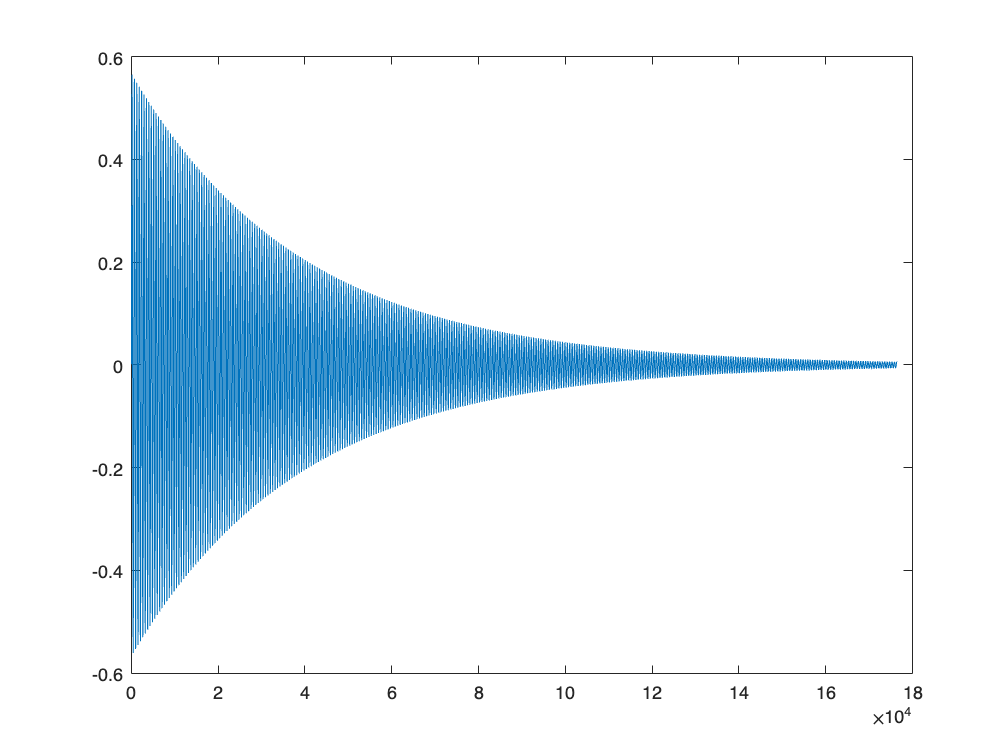

clc; clear;
% Basic parameters
fs = 44100;       % The sample rate, higher samplerate yields higher precision
T = 1 / fs;         % The sample period
N = fs * 4;         % The length of our output matrix
y = zeros(1, N);    % The output matrix

% Model parameters
k = 10000;      % The spring constant
m = 0.04;      % The mass of our mass
b = 0.09;      % The dampening coefficient

% State-space model states
x = [0.0; 0.0]; % The position and velocity states
u = [500000];   % The input force
u1 = [0.0];     % The previous input force

% State-space model matrices
A = [0 1; (-k/m) (-b/m)];               % Position/velocity contributions to derivatives
B = [0; 1/m];                           % Input forces contributions to derivatives
C = [1 0 ];                             % Output mapping
H = inv((2 / T) * eye(size(A)) - A);    % Matrix constant found using the trapezoid rule

% Main update loop
for i = 1:N
    % Apply the update rule
    x = H * ((2 / T) * eye(size(A)) + A) * x + H * B * (u + u1);
    % Do the output mapping
    y(i) = C * x;    
    % Store the current input force
    u1 = u;
    
    % Remove input force after first iteration
    if i == 1
        u = [0.0];
    end
end

plot(y);

soundsc(y, fs);
y

y =     0.0016    0.0064    0.0129    0.0193    0.0257    0.0321    0.0385    0.0449    0.0513    0.0577    0.0641    0.0705    0.0769    0.0832    0.0896    0.0959    0.1022    0.1085    0.1148    0.1211    0.1274    0.1336    0.1399    0.1461    0.1523    0.1584    0.1646    0.1707    0.1768    0.1829    0.1890    0.1950    0.2010    0.2070    0.2130    0.2189    0.2248    0.2307    0.2365    0.2423    0.2481    0.2539    0.2596    0.2653    0.2709    0.2765    0.2821    0.2876    0.2931    0.2986


## # Mass-Spring-Damper system using the forward Euler method

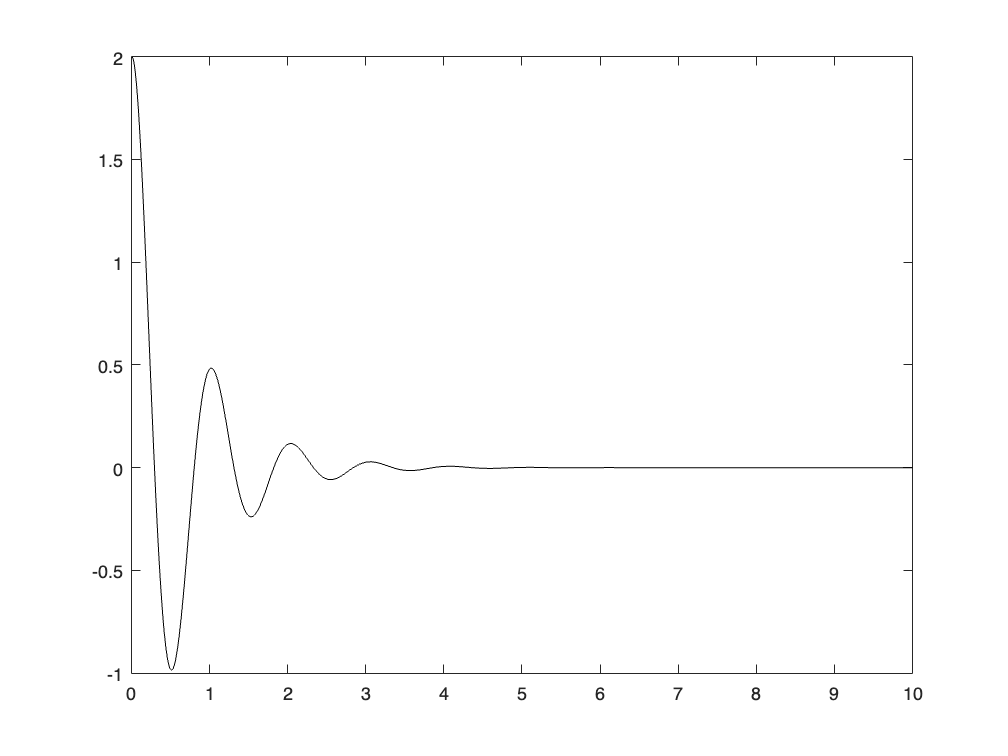

clc; clear;
% Mass-Spring-damper system
% ---------------------------

% Time attributes
ts = 0.01;                      % ts: time step
duration = 10;                  % duration: Amount of time

% System attributes
w = 2 * pi;                     % w: frequency
d = 0.25;                       % d: damping coefficient

% Matrix of system equations
A = [0 1; -w^2 -2*d*w];         % A: \dot{x} = A \cdot x

initX = [2; 0];                 % initX: Initial velocity & position

% Iterate forward Euler
forwardX(:,1) = initX;
forwardT(1) = 0;

for n=1:duration/ts
    forwardT(n+1) = n * ts;
    forwardX(:,n+1) = (eye(2) + ts * A) * forwardX(:,n);
end

plot(forwardT,forwardX(1,:),'k')

sound(forwardX);

## # Sustained bass

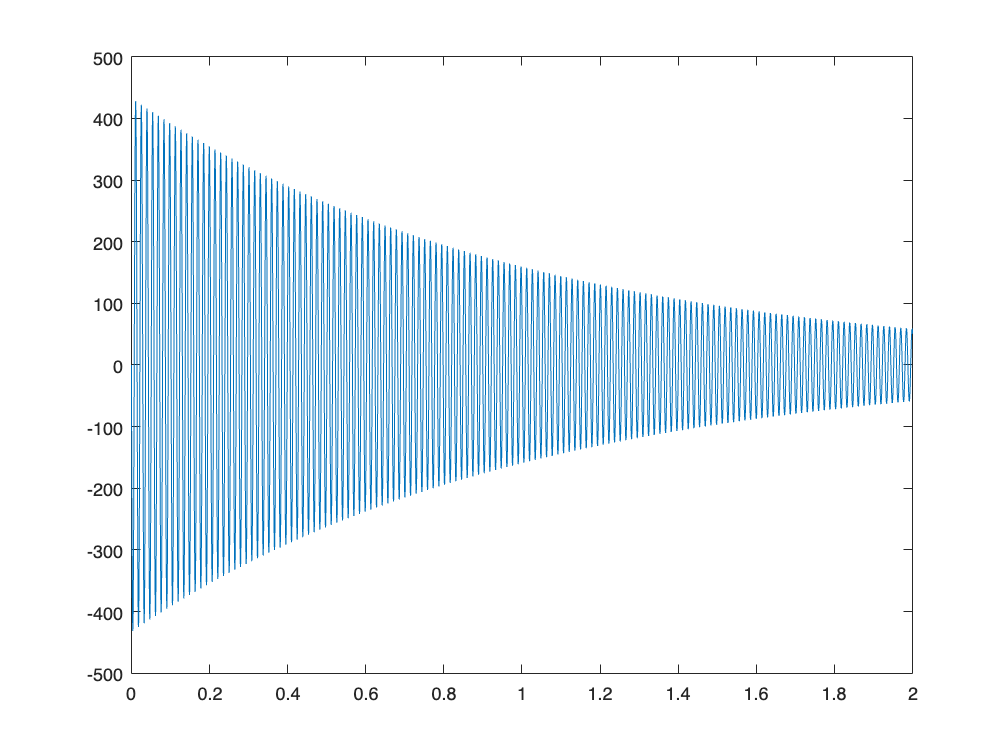

clc; clear;
% Mass-Spring-damper system
% ---------------------------

% Attributes
fs = 44100;                     % fs: sample rate
ts = 1 / fs;                    % ts: time step
duration = fs*2;                % duration: Amount of time = 2 seconds

% System attributes
k = 15000;                      % k: The spring constant
m = 0.08;                       % m: The mass 
b = 0.5;                        % b: The dampening coefficient

% Matrix of system equations
A = [0 1; (-k/m) (-b/m)];       % A: \dot{x} = A \cdot x

% Initialising matrixes
initX = [1; 0];                 % initX: Initial velocity & position
forwardX(:,1) = initX;              % forwardX: x_{n+1}
forwardT(1) = 0;                % forwardt: t_n

% Forward Euler integration update rule
for n=1:duration
    forwardT(n+1) = n * ts;
    forwardX(:,n+1) = (eye(2) + ts * A) * forwardX(:,n);
end

% Setting mono
forwardX(1, :) = [];

plot(forwardT, forwardX);

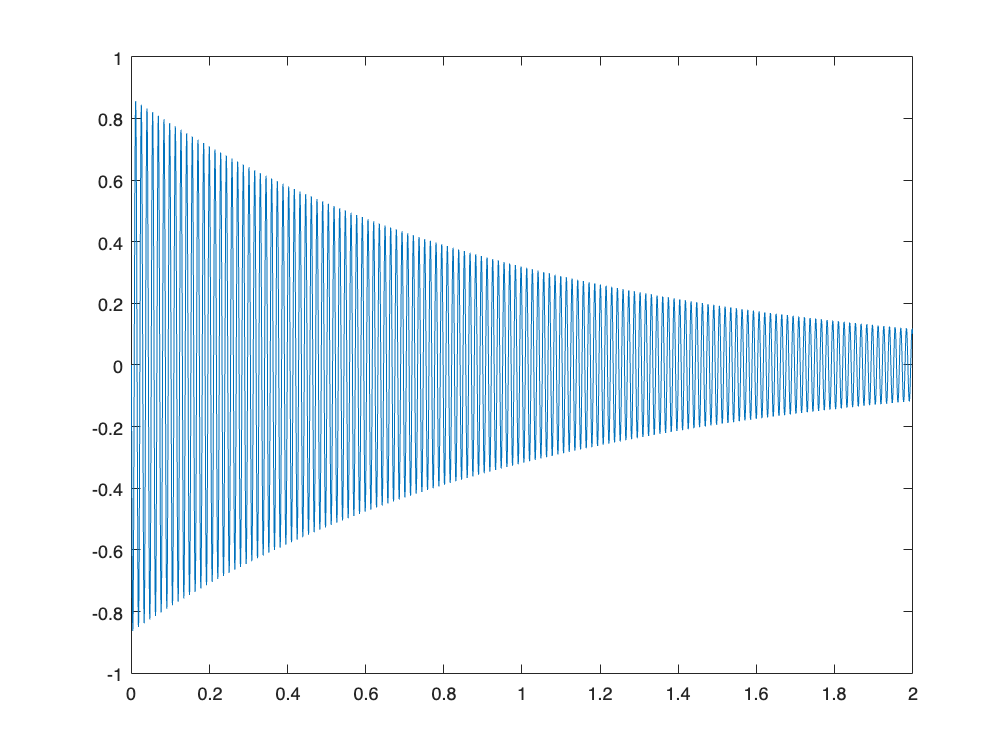


% Compressing the output -> Not meant to be needed
out = forwardX * 0.002;

plot(forwardT, out);

sound(out, fs);

## # Kick implementation

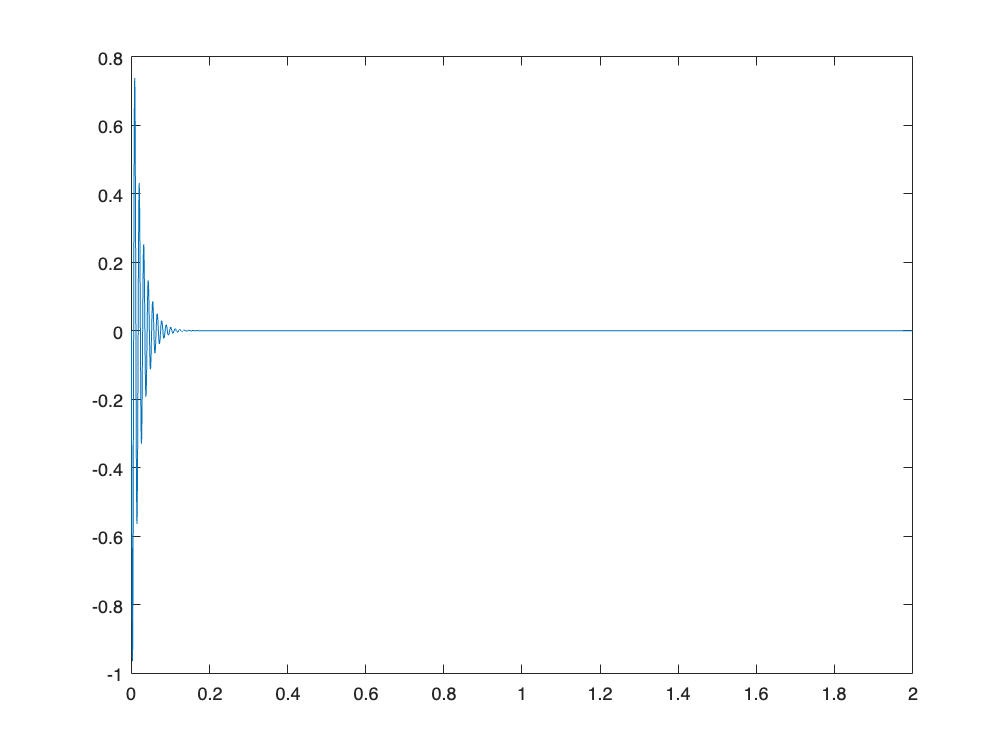

clc; clear;

% Mass-Spring-damper system
% ---------------------------

% Time attributes
fs = 44100;                     % fs: sample rate
ts = 1 / fs;                    % ts: time step
duration = fs*2;                % duration: Amount of time = 2 seconds

% System attributes
k = 3000;                       % k: The spring constant
m = 0.01;                       % m: The mass 
b = 1;                          % b: The dampening coefficient

% Matrix of system equations
A = [0 1; (-k/m) (-b/m)];       % A: \dot{x} = Ax

% Initialising matrixes
initX = [1; 0];                 % initX: Initial velocity & position
forwardX(:,1) = initX;          % forwardX: x_{n+1}
forwardT(1) = 0;                % forwardt: t_n

% Forward Euler integration update rule
for n=1:duration
    forwardT(n+1) = n * ts;
    forwardX(:,n+1) = (eye(2) + ts * A) * forwardX(:,n);
end

% Setting mono
forwardX(1, :) = [];

% Compressing the output -> Not meant to be needed
out = forwardX * 0.002;

plot(forwardT, out);

sound(out, fs);


## # Mass-spring-damper finite difference scheme

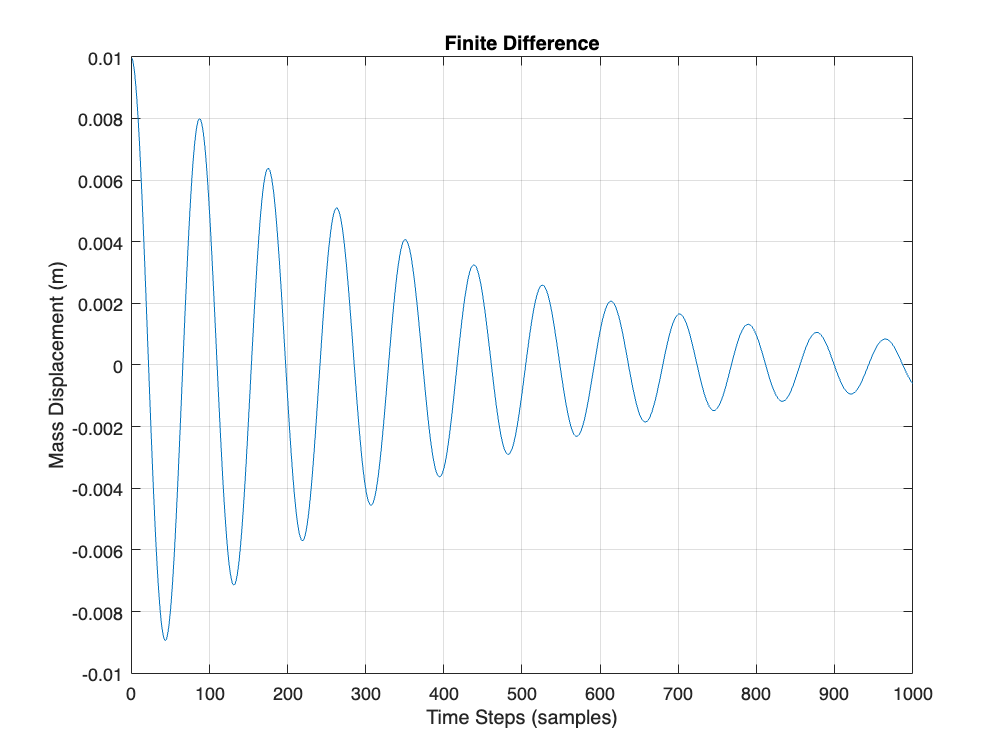

clc; clear;
% msd_fd.m
%
% Used to plot the solution of a mass-spring-damper system using
% a finite difference approach.
%
% Gary P. Scavone
% McGill University, 2004.

% Simulation Parameters

fs = 44100;      % sample rate
T = 1/fs;        % sample period
N = 1000;        % iterations

% System Parameters

m = 0.5;          % mass in kg
k = 5000000;      % spring constant (N/m)
w0 = sqrt(k/m);   % natural angular frequency of system
f0 = w0/(2*pi);   % natural frequency of system (no damping)
mu = 0.;         % damping constant
x0 = 0.01;        % initial displacement
v0 = 0;           % initial velocity

% System Equation: m(x'') + mu(x') + kx = 0, where x' = dx/dt

% Using the Laplace Transform:
%
% m(s^2*X(s) - s*x0 - v0) + mu(s*X(s) - x0) + k X(s) = 0
%
% X(s) = (m*s*x0 + m*v0 + mu*x0) / (m*s^2 + mu*s + k)

% Now do s-plane to z-plane mapping for the backward finite
% difference: s = (1-z^-1)/T and s^2 = (1 - 2z^-1 + z^-2)/T^2.
% Note that the constant initial condition terms in the numerator
% should be scaled by the sample rate (by a factor of 1/T) when
% converted from continuous to discrete time. Another way to
% think about this is a continuous delta function needs to be
% scaled by 1/T to maintain the same "integrated area" over time
% and to properly bandlimit it: delta(x) -> delta[n]/T:
%
% X(z) = 1/T*(b0 + b1*z^-1) / (a0 + a1*z^-1 + a2*z^-2),
%
% where:
b0 = m*x0*T + m*v0*T^2 + mu*x0*T^2;
b1 = -m*x0*T;
a0 = m + mu*T + k*T^2;
a1 = -(2*m + mu*T);
a2 = m;

% Now find the difference equation via the inverse z-Transform.
% 
%
% x[n] = b0/(T*a0)*delta[n] + b1/(T*a0)*delta[n-1] - a1/a0*x[n-1] - a2/a0*x[n-2]

% Displacement Initialization
x = zeros(1,N);
xm1 = 0;       % x[n-1]
xm2 = xm1;     % x[n-2]

% Now do simulation:
for n = 1:N
  
  x(n) = -xm1*a1 - xm2*a2;
  if n == 1
    x(n) = x(n) + b0/T;
  end
  if n == 2
      x(n) = x(n) + b1/T;
  end
  x(n) = x(n) / a0;
  xm2 = xm1;
  xm1 = x(n);
  
end

plot(x)
grid
xlabel('Time Steps (samples)');
ylabel('Mass Displacement (m)');
title('Finite Difference');


sound(x)

## # State-space modelling the mass-spring system

% Time attributes
Ts = 0.1
Tstart = 0
Tstop = 60

% System attributes
c = 1 % Damping constant

c = 1

k = 2 % Stiffness of the spring

k = 2

m = 10 % Mass

m = 10

F = 5 % Force

F = 5

Ts = 0.1000

Tstart = 0

Tstop = 60


N = (Tstop-Tstart) / Ts % Simulation length

N = 600


x1 = zeros(1, N)

x1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = zeros(1, N)

x2 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



x1(1) = 0 % Initial Position

x1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2(1) = 0 % Initial Speed

x2 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



a11 = 1

a11 = 1

a12 = Ts

a12 = 0.1000

a21 = -(Ts*k)/m

a21 = -0.0200

a22 = 1 - (Ts*c)/m

a22 = 0.9900


b1 = 0

b1 = 0

b2 = Ts/m

b2 = 0.0100

% Simulation
for n = 1:N
x1(n+1) = a11 * x1(n) + a12 * x2(n) + b1 * F;
x2(n+1) = a21 * x1(n) + a22 * x2(n) + b2 * F;
end

x1

x1 =          0         0    0.0050    0.0150    0.0298    0.0495    0.0739    0.1029    0.1365    0.1746    0.2171    0.2637    0.3145    0.3692    0.4277    0.4899    0.5557    0.6248    0.6971    0.7724    0.8506    0.9315    1.0148    1.1005    1.1882    1.2779    1.3693    1.4623    1.5565    1.6519    1.7483    1.8454    1.9430    2.0409    2.1390    2.2370    2.3347    2.4320    2.5287    2.6245    2.7193    2.8129    2.9052    2.9959    3.0848    3.1719    3.2570    3.3398    3.4204    3.4984


x2

x2 =          0    0.0500    0.0995    0.1484    0.1966    0.2441    0.2906    0.3362    0.3808    0.4243    0.4666    0.5075    0.5472    0.5854    0.6222    0.6574    0.6910    0.7230    0.7533    0.7818    0.8086    0.8335    0.8565    0.8776    0.8968    0.9141    0.9294    0.9427    0.9541    0.9634    0.9707    0.9760    0.9794    0.9807    0.9801    0.9775    0.9730    0.9666    0.9583    0.9481    0.9361    0.9224    0.9069    0.8897    0.8709    0.8505    0.8286    0.8052    0.7803    0.7541


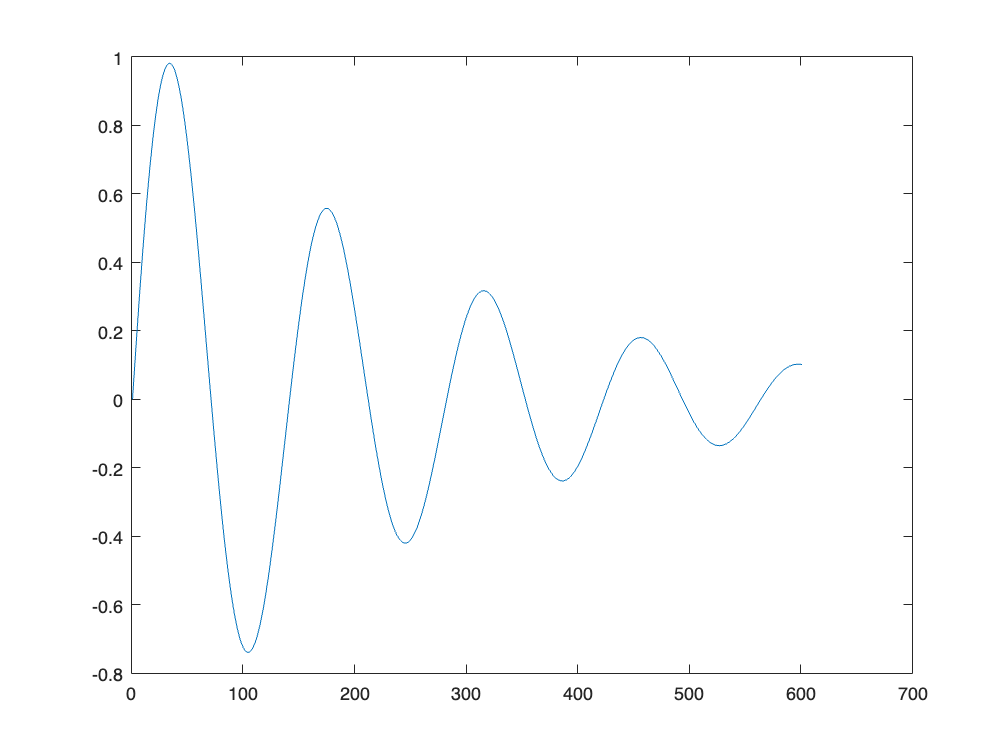


plot(x2)

sound(x2)

% Mass-Spring-damper system + input force
% ---------------------------

% Time attributes
fs = 44100;                         % fs: sample rate
ts = 1 / fs;                        % ts: time step
duration = fs*3;                    % duration: Amount of time = 3 seconds

% System attributes
k = 10000;                          % k: The spring constant                 
m = 0.02;                           % m: The mass
b = 0.3;                            % b: The dampening coefficient
u = 10;                             % u: Input force

% Matrices of system equations
A = [1  ts; -(ts*k)/m  1-(ts*b)/m]; % A: Ax
B = [0; ts/m];                      % B: Bu

% Initialising matrixes
x1 = zeros(1, duration);
x2 = zeros(1, duration);
x1(1) = 0; % Initial Position
x2(1) = 0; % Initial Speed

for n = 1:duration
    x1(n+1) = A(1, 1) * x1(n) + A(1, 2) * x2(n) + B(1) * u;
    x2(n+1) = A(2, 1) * x1(n) + A(2, 2) * x2(n) + B(2) * u;
end


x2 =          0    0.0113    0.0227    0.0340    0.0453    0.0566    0.0679    0.0792    0.0904    0.1017    0.1129    0.1240    0.1352    0.1463    0.1573    0.1683    0.1793    0.1902    0.2011    0.2120    0.2227    0.2334    0.2441    0.2547    0.2652    0.2757    0.2860    0.2963    0.3066    0.3167    0.3268    0.3368    0.3467    0.3565    0.3662    0.3758    0.3853    0.3947    0.4041    0.4133    0.4224    0.4314    0.4403    0.4490    0.4577    0.4662    0.4747    0.4829    0.4911    0.4992


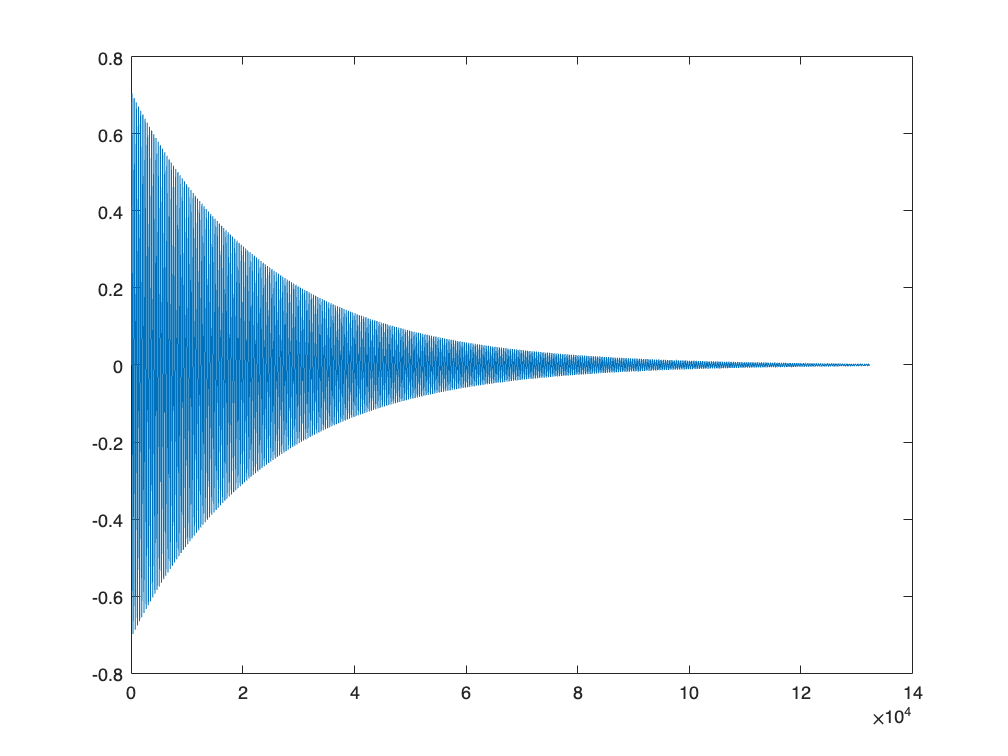

plot(x2)

sound(x2, fs)

## Design

Lorem Ipsum

## Implementation

Lorem Ipsum

## Conclusion

Lorem Ipsum